We want to model this function, from Kevin Uleck's presentation:

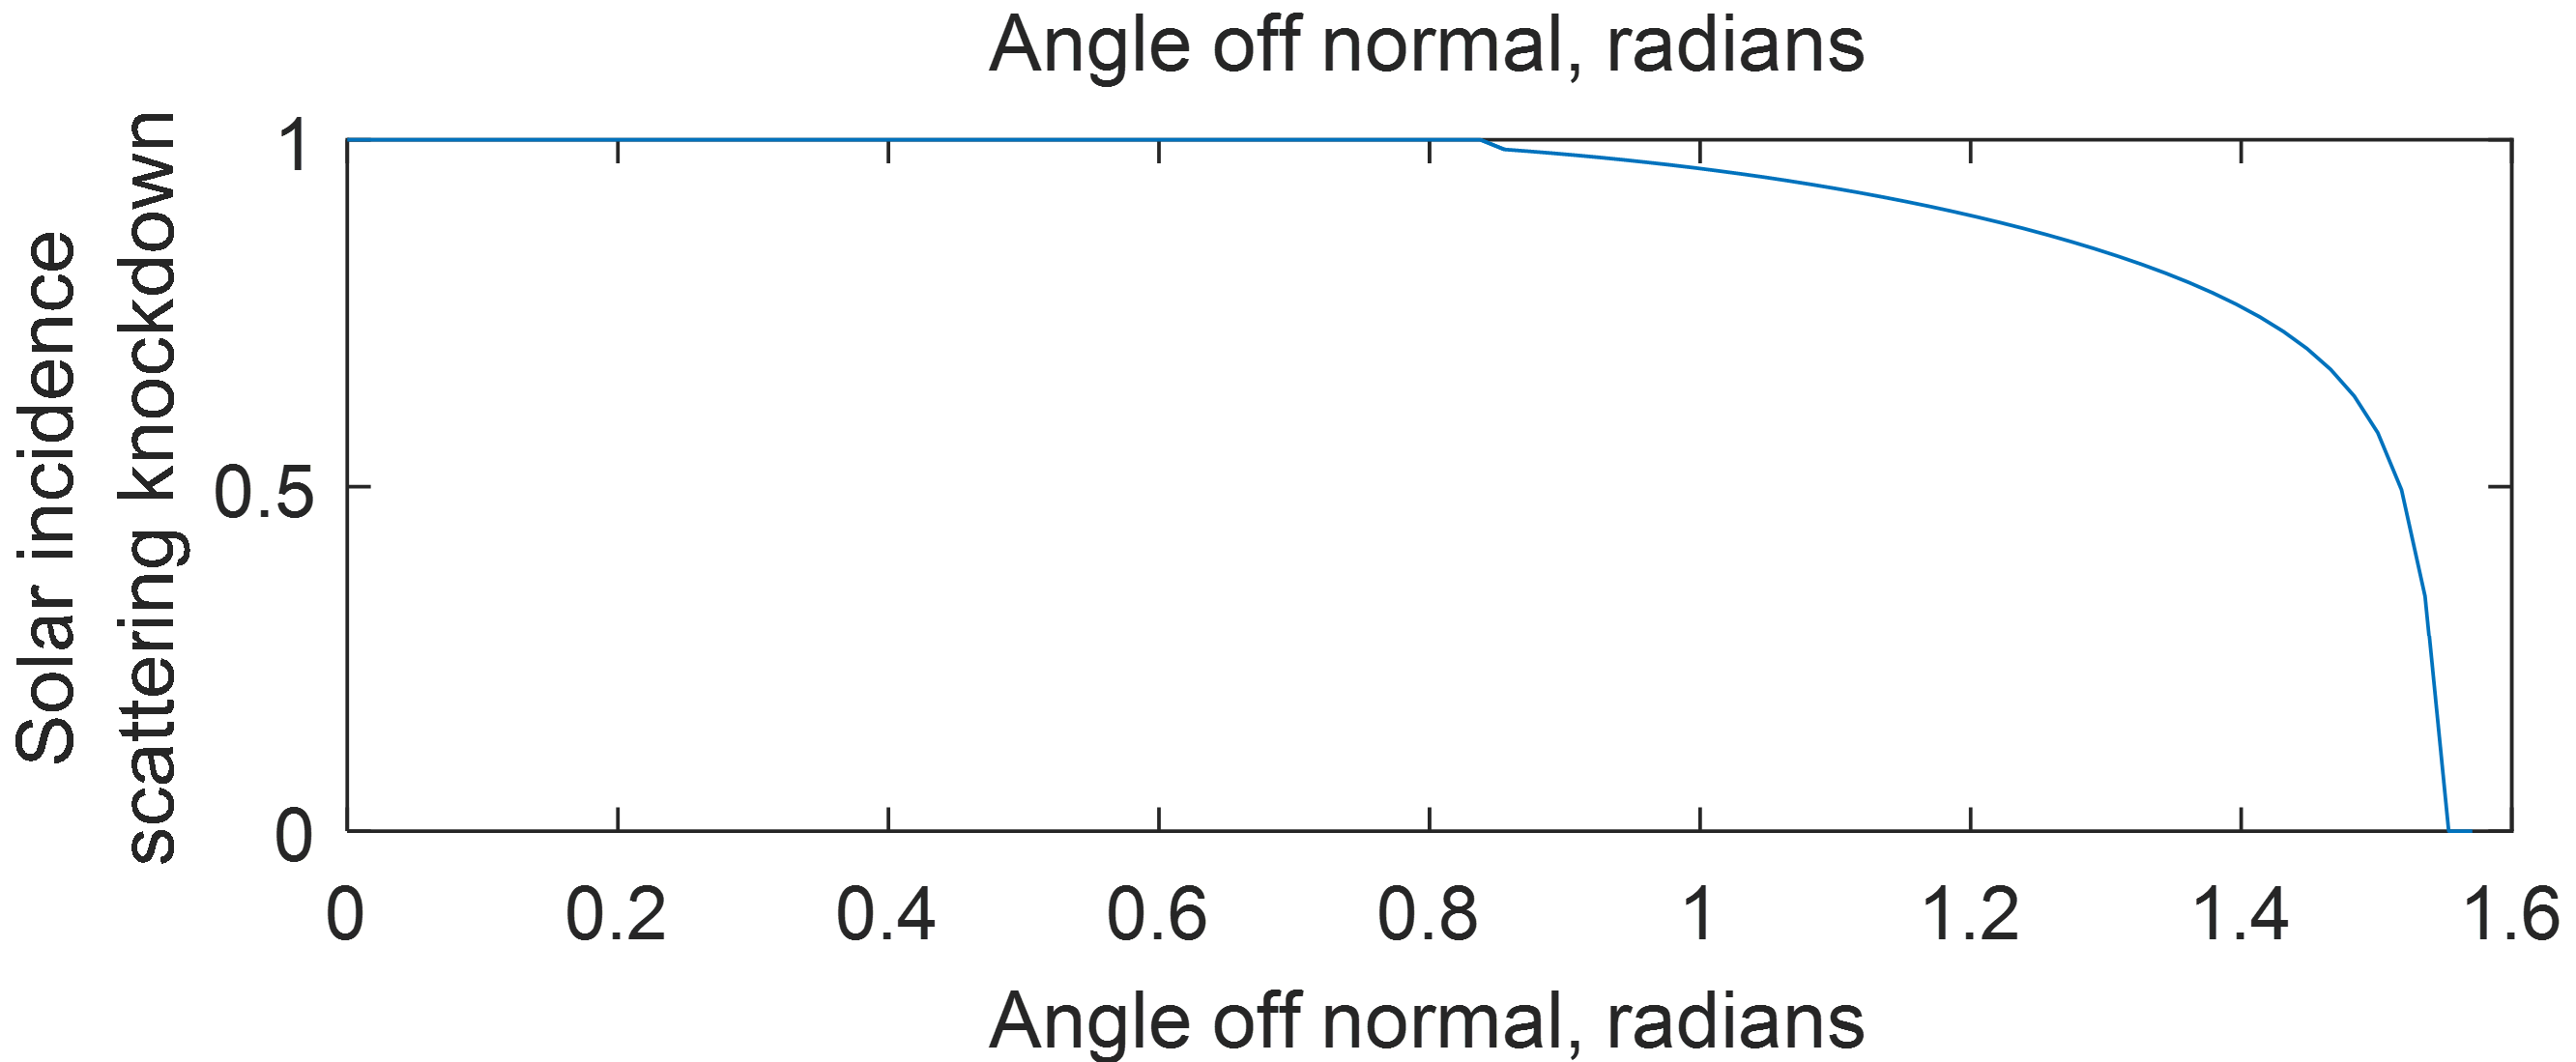

We sample some points

angle = [0.837
0.85
0.898
0.953
1.009
1.063
1.119
1.169
1.222
1.245
1.27
1.296
1.322
1.347
1.37
1.39
1.413
1.434
1.451
1.472
1.489
1.502
1.509
1.519
1.529
1.536
1.539
1.542
1.544
1.546
1.551
]

angle =     0.8370
    0.8500
    0.8980
    0.9530
    1.0090
    1.0630
    1.1190
    1.1690
    1.2220
    1.2450


knockdown = [1
0.991
0.982
0.969
0.958
0.938
0.922
0.902
0.882
0.873
0.853
0.839
0.824
0.806
0.788
0.77
0.746
0.719
0.692
0.654
0.614
0.569
0.531
0.469
0.386
0.299
0.25
0.19
0.123
0.058
0.013
]

knockdown =     1.0000
    0.9910
    0.9820
    0.9690
    0.9580
    0.9380
    0.9220
    0.9020
    0.8820
    0.8730


And we do some curve fitting.

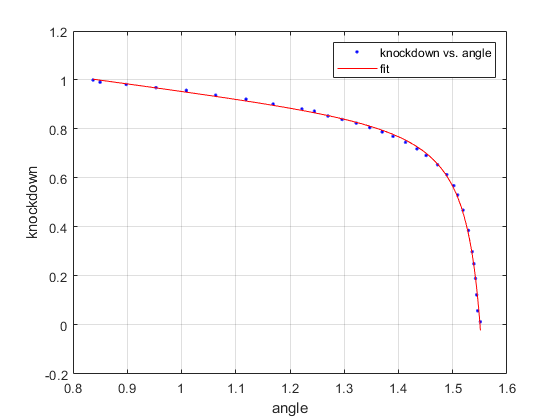

fit =      General model:
     fit(x) = c0 + c4*x + exp(c1*(tan(x)+c2*x))
     Coefficients (with 95% confidence bounds):
       c0 =      0.2789  (0.1838, 0.3741)
       c1 =    -0.01599  (-0.02003, -0.01196)
       c2 =      -19.71  (-31.54, -7.874)
       c4 =     -0.6626  (-0.906, -0.4193)

fit = createFit(angle, knockdown)

vpa(fit.c0)

$$ans = 0.27891510500505767300438719757949$$

vpa(fit.c1)

$$ans = -0.015994330894744987481281839336589$$

vpa(fit.c2)

$$ans = -19.707332432605799255043166340329$$

vpa(fit.c4)

$$ans = -0.66260979582573353852126274432521$$

fit(pi/2)

ans = -0.7619